close all; clc;

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by Neural Pattern Recognition app
% This script assumes these variables are defined:
%
%   score - input data.
%   label - target data.
% for i = 1:30;

## Neural Network Input

components = 1:45; % Choosen PCs
x = score(:,components)';
t = label';

rng(30); % fixed seed

trainFcn = 'trainscg';  % Scaled conjugate gradient bacpropagation.


## Create a Pattern Recognition Network

hiddenLayerSize = 35;
net = patternnet(hiddenLayerSize, trainFcn);

% Choose Input and Output Pre/Post-Processing Functions
% For a list of all processing functions type: help nnprocess
net.input.processFcns = {'removeconstantrows','mapminmax'};


## Setup Division of Data for Training, Validation, Testing

net.divideFcn = 'dividerand';  % Divide data randomly
net.divideMode = 'sample';  % Divide up every sample
net.divideParam.trainRatio =70/100;
net.divideParam.valRatio = 10/100;
net.divideParam.testRatio = 20/100;

## HyperParameters

net.trainparam.lr = 0.001; % learning rate
net.trainParam.epochs = 1000; % number of epochs
net.trainParam.goal = 1e-5; % goal
net.trainParam.max_fail = 6; % maximum validation fails
net.trainParam.min_grad = 1e-8;
net.trainParam.showCommandLine = true;
net.trainParam.showWindow = true;
% Choose a Performance Function
% For a list of all performance functions type: help nnperformance
net.performFcn = 'crossentropy';  % Cross-Entropy

% Choose Plot Functions
% For a list of all plot functions type: help nnplot
net.plotFcns = {'plotperform','plottrainstate','ploterrhist','plotconfusion', 'plotroc'};

## Train Network

[net,tr] = train(net,x,t);

Calculation mode: MEX
 
Training Pattern Recognition Neural Network with TRAINSCG.
Epoch 0/1000, Time 0.099, Performance 0.7794/1e-05, Gradient 0.7171/1e-08, Validation Checks 0/6
Epoch 11/1000, Time 0.168, Performance 0.010101/1e-05, Gradient 0.024373/1e-08, Validation Checks 6/6
Training with TRAINSCG completed: Validation stop.
 


## Test Network

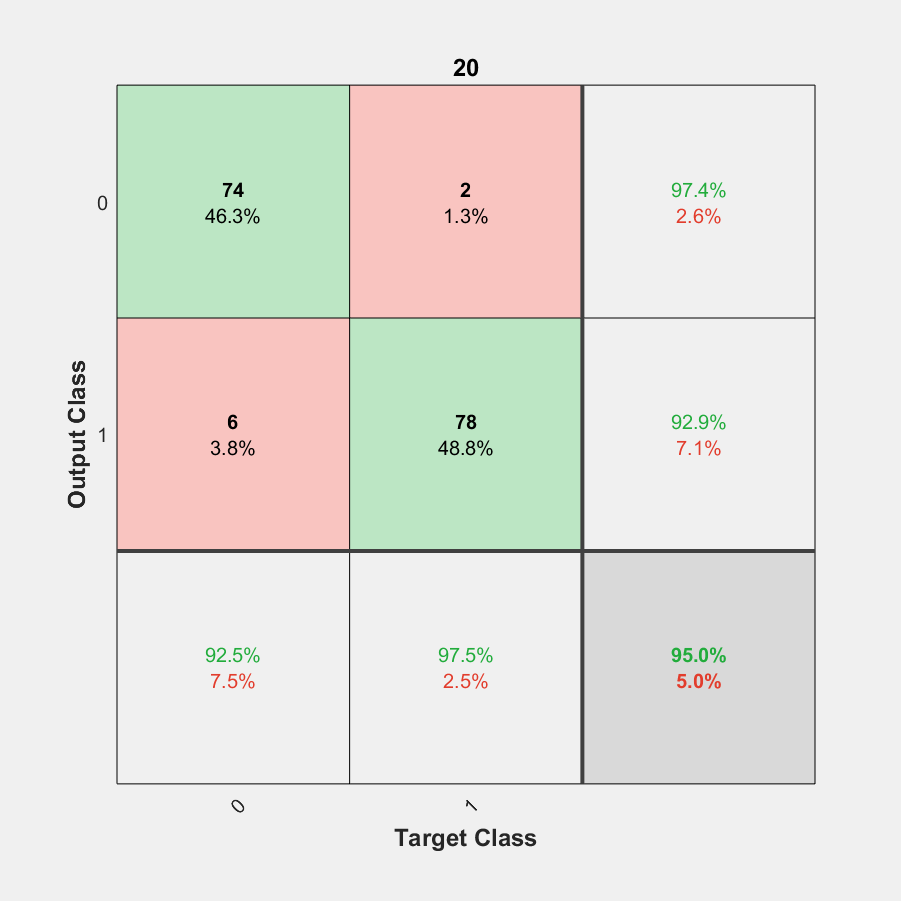

y = net(x);
e = gsubtract(t,y);
tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind);

w1 = net.IW{1}; %the input-to-hidden layer weights
w2 = net.LW{2}; %the hidden-to-output layer weights
b1 = net.b{1}; %the input-to-hidden layer bias
b2 = net.b{2}; %the input-to-hidden layer bias
% Recalculate Training, Validation and Test Performance
trainTargets = t .* tr.trainMask{1};
valTargets = t .* tr.valMask{1};
testTargets = t .* tr.testMask{1};
trainPerformance = perform(net,trainTargets,y);
valPerformance = perform(net,valTargets,y);
testPerformance = perform(net,testTargets,y);
performance = perform(net,t,y);
figure, plotconfusion(t,y); title(sprintf("%i",i))